# Getting Started with MATLAB Interface for Apache Parquet®

## Description

Provides native MATLAB support for reading and writing Apache Parquet® files

## System Requirements

MATLAB 2017b or greater.

Windows, Linux and Mac compatible

## Features

Provides easy to use MATLAB functions to read and write Parquet files

Supported features include:

- Writing MATLAB datatypes to Parquet

- Snappy, gzip compression supported natively for read and write

- Automatic schema generation on write

- Reading Parquet files to native MATLAB types automatically

- Tall array support including using PCT and Hadoop/Spark 

- MATLAB datatypes preserved on read. i.e. write a `timetable` to Parquet file, reads back a `timetable`

- Supports local filesystem and HDFS

# Windows Users

To write Parquet files using MATLAB, the steps for downloading winutils and setting up HADOOP_HOME are done during the install phase. If any of the steps were deferred for later, then this section goes into detail on how to go through the setup manually.

#### Setup verification

To verify all is setup correctly run the below and follow the suggestions if there are problems. 

parquetwin('verify')

If everything is OK, you should see the below:

The below documents the steps needed to fix anyof the above  setup issues.

#### Set HADOOP_HOME

If you ran `parquet('verify') `and got the below message, where `C:\MyFolder\ParquetInstallfolder` is the folder where the Parquet code is installed on your machine:

 Run the following command, this will display the value needed for `HADOOP_HOME`

parquetwin('hadoop_home')

Next, open the environment variables editor in Windows, and paste the `HADOOP_HOME` System variable. It should look something like this:

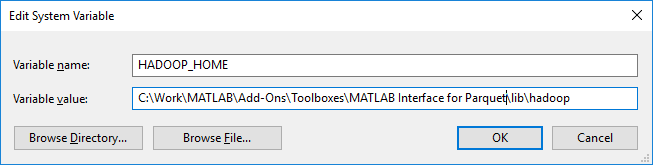

#### Download winutils 

If you ran `parquet('verify') `and got the below message, where `C:\MyFolder\ParquetInstallfolder` is the folder where the Parquet code is installed on your machine:

Ensure you have downloaded [winutils](https://github.com/steveloughran/winutils/raw/master/hadoop-2.8.3/bin/winutils.exe), the below should return `true` indicating succesfull download:

parquetwin('installWinutils')

#### Testing winutils

If you ran `parquet('verify') `and got the below message:

This can occur in situations like a clean Windows Server 2016 install on Azure for instance, and the most likely cause is a missing DLL. If you see a **MSVCR100.dll is missing** message popup then you will need to install:

[Microsoft Visual C++ 2010 SP1 Redistributable Package (x64)](https://www.microsoft.com/en-US/download/details.aspx?id=13523)

#### Restart MATLAB

Always restart MATLAB after either Toolbox install, plain vanilla install or after setting `HADOOP_HOME`

# Example

Open the [Demo](matlab:edit('parquetDemo.mlx')) to get started with some examples

# Limitations

This release does not support the following datatypes when reading Parquet files:

- Nested types LIST, MAP

- BYTE_ARRAY: arbitrarily long byte arrays

- ENUM

- UUID

- DECIMAL

- JSON

- BSON